# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

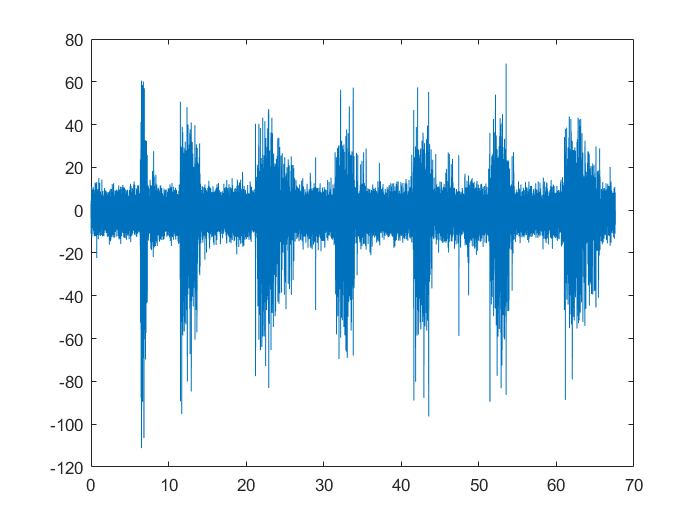

%uso della funzione get_envelope() 

fs = 2000;
nfft= 1024;

signal = cell2mat(emg_data(1));

%
figure
plot(signal(:,1), signal(:,2))

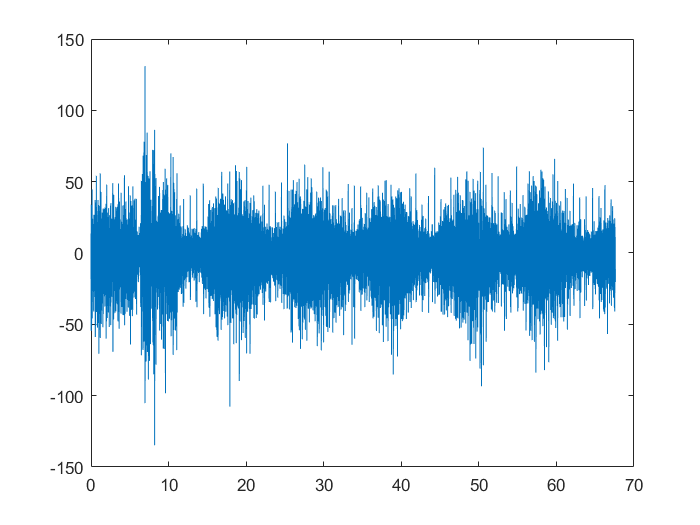

figure
plot(signal(:,1), signal(:,3))

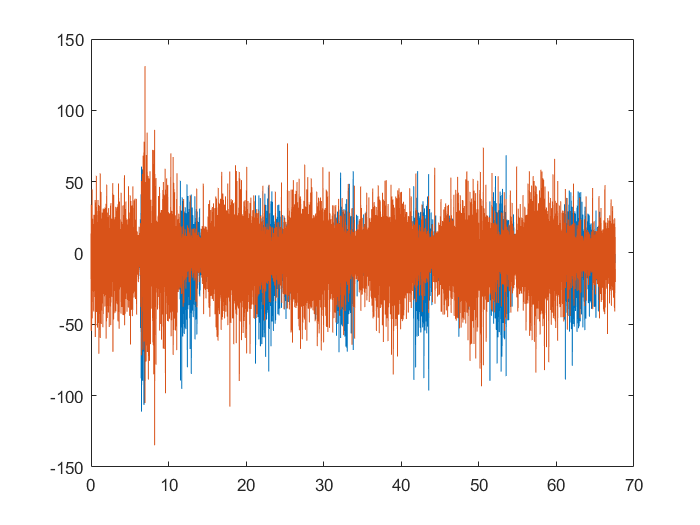

figure
plot(signal(:,1), signal(:,2)), hold on, plot(signal(:,1),signal(:,3))

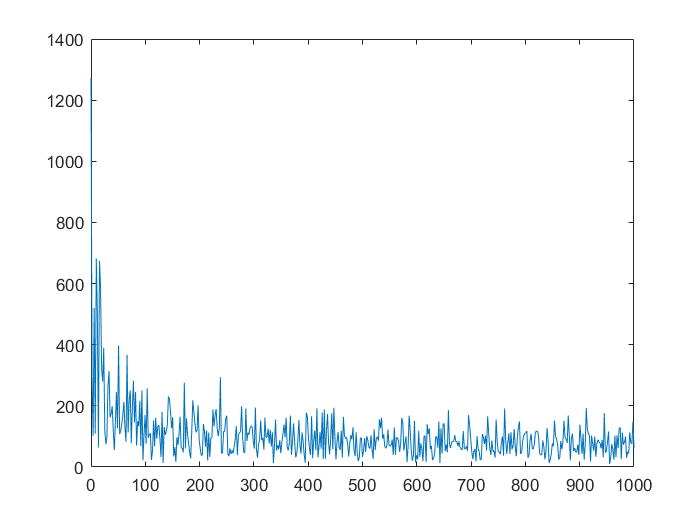


%primo muscolo
yF1= fft (signal(:,2), nfft);
f=linspace(0, fs/2, floor(nfft/2)+1);

figure 
plot(f,abs(yF1(1:floor(nfft/2)+1)))


[~, iF] = max(abs(yF1(1:floor(nfft/2)+1)));
% f_peak = f (iF)
% 
% Wn= [1, f_peak + 20] / (fs/2) 
Wn= [4, 10] / (fs/2)

Wn =     0.0040    0.0100


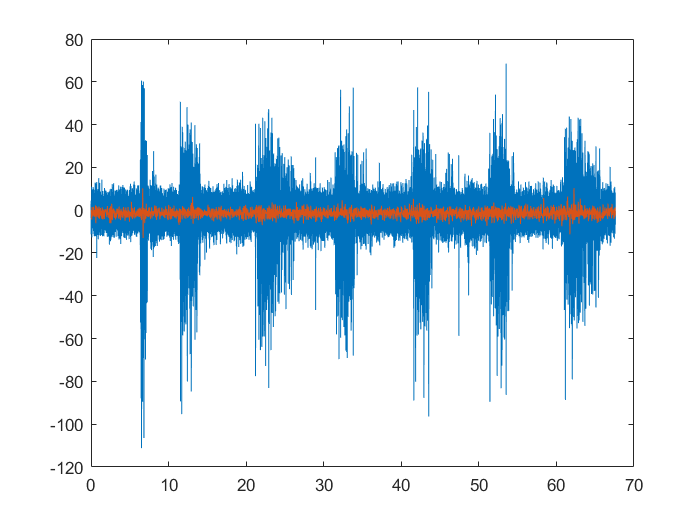


[b,a] = fir1(200,Wn);

sig_filtered = filter(b, a, signal(:,2));
figure, plot(signal(:,1),signal(:,2)), hold on, plot(signal(:,1), sig_filtered);

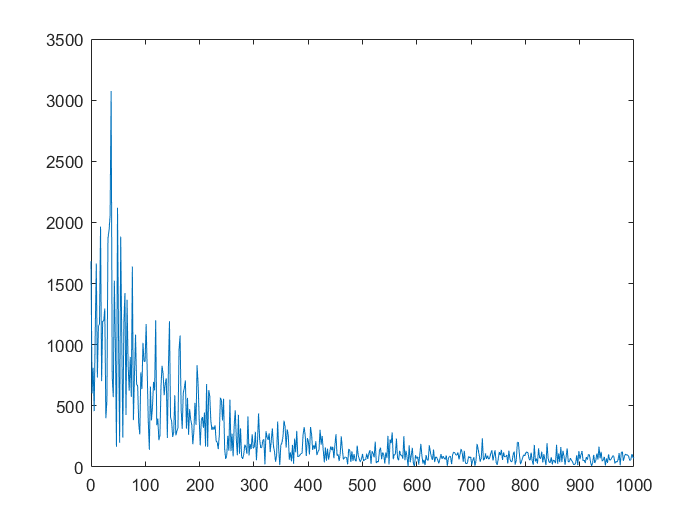


%secondo muscolo

yF= fft (signal(:,3), nfft);
f=linspace(0, fs/2, floor(nfft/2)+1);

figure 
plot(f,abs(yF(1:floor(nfft/2)+1)))


[~, iF] = max(abs(yF(1:floor(nfft/2)+1)));
f_peak = f (iF)

f_peak = 37.1094


Wn= [f_peak - 5, f_peak + 5] / (fs/2) 

Wn =     0.0321    0.0421


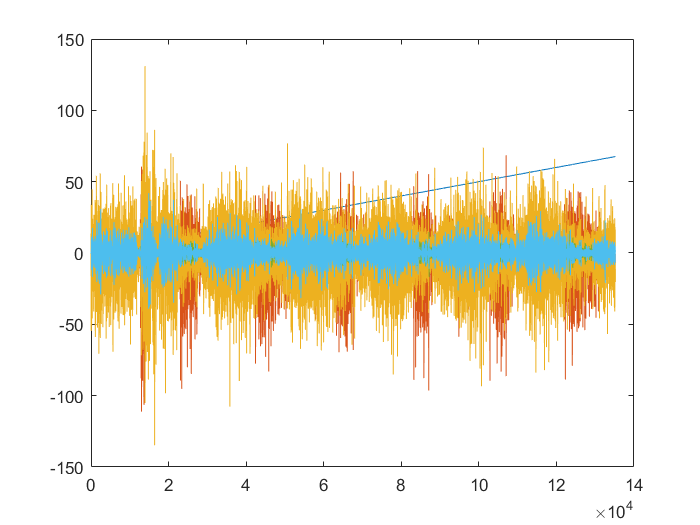


[b,a] = fir1(200,Wn);

sig_filtered = filter(b, a, signal);
figure, plot(signal), hold on, plot(sig_filtered);

*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

%uso funzione data_normalization()

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

...

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

%uso funzione detect_activation()

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

...

*Obiettivo 6: calcolaree visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

...

*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

%uso funzione my_permutation_test()